**MINIMIZATION OF TIME AND CONTROL**

import casadi.*
opti = casadi.Opti();

T = opti.variable(); %time horizon
N = 50; % no of sampling points
dt = T/N;

X = opti.variable(4, N+1) %states over time

X = opti4_x_2


U = opti.variable(2, N) % control inputs over time

U = opti4_x_3


x0 = [-5; -4; 0; 0] %initial state

x0 =     -5
    -4
     0
     0


xf = [pi/2; 0; 0; 0] %final state

xf =     1.5708
         0
         0
         0



% parameters
b1 = 200.0;
b2 = 50.0;
b3 = 23.5;
b4 = 25.0;
b5 = 122.5;
c1 = -25.0;
g1 = 784.8;
g2 = 245.3;


%dynamics
f = @(X, U) [X(3);
    X(4);
    -(b5*U(1) - b3*U(2) - b5*g1*cos(X(1)) - b4*U(2)*cos(X(2)) + b3*g2*cos(X(1) + X(2)) - b5*g2*cos(X(1) + X(2)) + b4*g2*cos(X(1) + X(2))*cos(X(2)) + b3*c1*X(3)^2*sin(X(2)) + b5*c1*X(4)^2*sin(X(2)) + b4*c1*X(3)^2*cos(X(2))*sin(X(2)) + 2*b5*c1*X(3)*X(4)*sin(X(2)))/(b4^2*cos(X(2))^2 - b1*b5 + b3^2 - b2*b5*cos(X(2)) + 2*b3*b4*cos(X(2)));
    (b3*U(1) - b1*U(2) - b3*g1*cos(X(1)) - b2*U(2)*cos(X(2)) + b4*U(1)*cos(X(2)) + b1*g2*cos(X(1) + X(2)) - b3*g2*cos(X(1) + X(2)) + b2*g2*cos(X(1) + X(2))*cos(X(2)) - b4*g2*cos(X(1) + X(2))*cos(X(2)) - b4*g1*cos(X(1))*cos(X(2)) + b1*c1*X(3)^2*sin(X(2)) + b3*c1*X(4)^2*sin(X(2)) + b2*c1*X(3)^2*cos(X(2))*sin(X(2)) + b4*c1*X(4)^2*cos(X(2))*sin(X(2)) + 2*b3*c1*X(3)*X(4)*sin(X(2)) + 2*b4*c1*X(3)*X(4)*cos(X(2))*sin(X(2)))/(b4^2*cos(X(2))^2 - b1*b5 + b3^2 - b2*b5*cos(X(2)) + 2*b3*b4*cos(X(2)))]

f = function_handle with value:
    @(X,U)[X(3);X(4);-(b5*U(1)-b3*U(2)-b5*g1*cos(X(1))-b4*U(2)*cos(X(2))+b3*g2*cos(X(1)+X(2))-b5*g2*cos(X(1)+X(2))+b4*g2*cos(X(1)+X(2))*cos(X(2))+b3*c1*X(3)^2*sin(X(2))+b5*c1*X(4)^2*sin(X(2))+b4*c1*X(3)^2*cos(X(2))*sin(X(2))+2*b5*c1*X(3)*X(4)*sin(X(2)))/(b4^2*cos(X(2))^2-b1*b5+b3^2-b2*b5*cos(X(2))+2*b3*b4*cos(X(2)));(b3*U(1)-b1*U(2)-b3*g1*cos(X(1))-b2*U(2)*cos(X(2))+b4*U(1)*cos(X(2))+b1*g2*cos(X(1)+X(2))-b3*g2*cos(X(1)+X(2))+b2*g2*cos(X(1)+X(2))*cos(X(2))-b4*g2*cos(X(1)+X(2))*cos(X(2))-b4*g1*cos(X(1))*cos(X(2))+b1*c1*X(3)^2*sin(X(2))+b3*c1*X(4)^2*sin(X(2))+b2*c1*X(3)^2*cos(X(2))*sin(X(2))+b4*c1*X(4)^2*cos(X(2))*sin(X(2))+2*b3*c1*X(3)*X(4)*sin(X(2))+2*b4*c1*X(3)*X(4)*cos(X(2))*sin(X(2)))/(b4^2*cos(X(2))^2-b1*b5+b3^2-b2*b5*cos(X(2))+2*b3*b4*cos(X(2)))]



% constraints
Umin = -1000;
Umax = 1000;
Qdotmin = -3*pi/2;
Qdotmax = 3*pi/2;
opti.subject_to(Umin <= U <= Umax);
opti.subject_to(X(:,1)==x0);
opti.subject_to(X(:,N+1)==xf);
opti.subject_to(Qdotmin <= X(3,:)<= Qdotmax)
opti.subject_to(Qdotmin <= X(4,:)<= Qdotmax)
opti.subject_to(T >= 0);


J=0;
for k =1:N
    %Runge-kutta integration
    k1 = f(X(:, k), U(:, k)); 
    k2 = f(X(:,k)+dt/2*k1, U(:,k));
    k3 = f(X(:,k)+dt/2*k2, U(:,k));
    k4 = f(X(:,k)+dt*k3, U(:,k));
    x_next = X(:,k) + dt/6*(k1+2*k2+2*k3+k4)
    % Euler integration
%     x_next = X(:, k) + dt*f(X(:, k), U(:, k));
    opti.subject_to(X(:, k+1)==x_next);
%     opti.subject_to(Umin <= U <= Umax);
%     opti.subject_to(Qdotmin <= X(3,:)<= Qdotmax)
%     opti.subject_to(Qdotmin <= X(4,:)<= Qdotmax)
    J = J + dt*(U(:, k)'*U(:,k));
end

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[2], opti4_x_2[3], (-((((((((((((122.5*opti4_x_3[0])-(23.5*opti4_x_3[1]))-(96138*cos(opti4_x_2[0])))-((25*opti4_x_3[1])*cos(opti4_x_2[1])))+(5764.55*cos((opti4_x_2[0]+opti4_x_2[1]))))-(30049.2*cos((opti4_x_2[0]+opti4_x_2[1]))))+((6132.5*cos((opti4_x_2[0]+opti4_x_2[1])))*cos(opti4_x_2[1])))+((-587.5*sq(opti4_x_2[2]))*sin(opti4_x_2[1])))+((-3062.5*sq(opti4_x_2[3]))*sin(opti4_x_2[1])))+(((-625*sq(opti4_x_2[2]))*cos(opti4_x_2[1]))*sin(opti4_x_2[1])))+(((-6125*opti4_x_2[2])*opti4_x_2[3])*sin(opti4_x_2[1])))/(((552.25+((625*sq(cos(opti4_x_2[1])))-24500))-(6125*cos(opti4_x_2[1])))+(1175*cos(opti4_x_2[1]))))), (((((((((((((((((23.5*opti4_x_3[0])-(200*opti4_x_3[1]))-(18442.8*cos(opti4_x_2[0])))-((50*opti4_x_3[1])*cos(opti4_x_2[1])))+((25*opti4_x_3[0])*cos(opti4_x_2[1])))+(49060*cos((opti4_x_2[0]+opti4_x_2[1]))))-(5764.55*cos((opti4_x_2[0]+opti4_x_2[1]))))+((12265*cos((opti4_x_2[0]+opti4_x_2[1])))*cos(opti4_x_2[1])))-((6132.5*cos((opti4_x_2[0]+opti

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[6], opti4_x_2[7], (-((((((((((((122.5*opti4_x_3[2])-(23.5*opti4_x_3[3]))-(96138*cos(opti4_x_2[4])))-((25*opti4_x_3[3])*cos(opti4_x_2[5])))+(5764.55*cos((opti4_x_2[4]+opti4_x_2[5]))))-(30049.2*cos((opti4_x_2[4]+opti4_x_2[5]))))+((6132.5*cos((opti4_x_2[4]+opti4_x_2[5])))*cos(opti4_x_2[5])))+((-587.5*sq(opti4_x_2[6]))*sin(opti4_x_2[5])))+((-3062.5*sq(opti4_x_2[7]))*sin(opti4_x_2[5])))+(((-625*sq(opti4_x_2[6]))*cos(opti4_x_2[5]))*sin(opti4_x_2[5])))+(((-6125*opti4_x_2[6])*opti4_x_2[7])*sin(opti4_x_2[5])))/(((552.25+((625*sq(cos(opti4_x_2[5])))-24500))-(6125*cos(opti4_x_2[5])))+(1175*cos(opti4_x_2[5]))))), (((((((((((((((((23.5*opti4_x_3[2])-(200*opti4_x_3[3]))-(18442.8*cos(opti4_x_2[4])))-((50*opti4_x_3[3])*cos(opti4_x_2[5])))+((25*opti4_x_3[2])*cos(opti4_x_2[5])))+(49060*cos((opti4_x_2[4]+opti4_x_2[5]))))-(5764.55*cos((opti4_x_2[4]+opti4_x_2[5]))))+((12265*cos((opti4_x_2[4]+opti4_x_2[5])))*cos(opti4_x_2[5])))-((6132.5*cos((opti4_x_2[4]+opti

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[10], opti4_x_2[11], (-((((((((((((122.5*opti4_x_3[4])-(23.5*opti4_x_3[5]))-(96138*cos(opti4_x_2[8])))-((25*opti4_x_3[5])*cos(opti4_x_2[9])))+(5764.55*cos((opti4_x_2[8]+opti4_x_2[9]))))-(30049.2*cos((opti4_x_2[8]+opti4_x_2[9]))))+((6132.5*cos((opti4_x_2[8]+opti4_x_2[9])))*cos(opti4_x_2[9])))+((-587.5*sq(opti4_x_2[10]))*sin(opti4_x_2[9])))+((-3062.5*sq(opti4_x_2[11]))*sin(opti4_x_2[9])))+(((-625*sq(opti4_x_2[10]))*cos(opti4_x_2[9]))*sin(opti4_x_2[9])))+(((-6125*opti4_x_2[10])*opti4_x_2[11])*sin(opti4_x_2[9])))/(((552.25+((625*sq(cos(opti4_x_2[9])))-24500))-(6125*cos(opti4_x_2[9])))+(1175*cos(opti4_x_2[9]))))), (((((((((((((((((23.5*opti4_x_3[4])-(200*opti4_x_3[5]))-(18442.8*cos(opti4_x_2[8])))-((50*opti4_x_3[5])*cos(opti4_x_2[9])))+((25*opti4_x_3[4])*cos(opti4_x_2[9])))+(49060*cos((opti4_x_2[8]+opti4_x_2[9]))))-(5764.55*cos((opti4_x_2[8]+opti4_x_2[9]))))+((12265*cos((opti4_x_2[8]+opti4_x_2[9])))*cos(opti4_x_2[9])))-((6132.5*cos((opti4_x_2[

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[14], opti4_x_2[15], (-((((((((((((122.5*opti4_x_3[6])-(23.5*opti4_x_3[7]))-(96138*cos(opti4_x_2[12])))-((25*opti4_x_3[7])*cos(opti4_x_2[13])))+(5764.55*cos((opti4_x_2[12]+opti4_x_2[13]))))-(30049.2*cos((opti4_x_2[12]+opti4_x_2[13]))))+((6132.5*cos((opti4_x_2[12]+opti4_x_2[13])))*cos(opti4_x_2[13])))+((-587.5*sq(opti4_x_2[14]))*sin(opti4_x_2[13])))+((-3062.5*sq(opti4_x_2[15]))*sin(opti4_x_2[13])))+(((-625*sq(opti4_x_2[14]))*cos(opti4_x_2[13]))*sin(opti4_x_2[13])))+(((-6125*opti4_x_2[14])*opti4_x_2[15])*sin(opti4_x_2[13])))/(((552.25+((625*sq(cos(opti4_x_2[13])))-24500))-(6125*cos(opti4_x_2[13])))+(1175*cos(opti4_x_2[13]))))), (((((((((((((((((23.5*opti4_x_3[6])-(200*opti4_x_3[7]))-(18442.8*cos(opti4_x_2[12])))-((50*opti4_x_3[7])*cos(opti4_x_2[13])))+((25*opti4_x_3[6])*cos(opti4_x_2[13])))+(49060*cos((opti4_x_2[12]+opti4_x_2[13]))))-(5764.55*cos((opti4_x_2[12]+opti4_x_2[13]))))+((12265*cos((opti4_x_2[12]+opti4_x_2[13])))*cos(opti4_x_2[13])

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[18], opti4_x_2[19], (-((((((((((((122.5*opti4_x_3[8])-(23.5*opti4_x_3[9]))-(96138*cos(opti4_x_2[16])))-((25*opti4_x_3[9])*cos(opti4_x_2[17])))+(5764.55*cos((opti4_x_2[16]+opti4_x_2[17]))))-(30049.2*cos((opti4_x_2[16]+opti4_x_2[17]))))+((6132.5*cos((opti4_x_2[16]+opti4_x_2[17])))*cos(opti4_x_2[17])))+((-587.5*sq(opti4_x_2[18]))*sin(opti4_x_2[17])))+((-3062.5*sq(opti4_x_2[19]))*sin(opti4_x_2[17])))+(((-625*sq(opti4_x_2[18]))*cos(opti4_x_2[17]))*sin(opti4_x_2[17])))+(((-6125*opti4_x_2[18])*opti4_x_2[19])*sin(opti4_x_2[17])))/(((552.25+((625*sq(cos(opti4_x_2[17])))-24500))-(6125*cos(opti4_x_2[17])))+(1175*cos(opti4_x_2[17]))))), (((((((((((((((((23.5*opti4_x_3[8])-(200*opti4_x_3[9]))-(18442.8*cos(opti4_x_2[16])))-((50*opti4_x_3[9])*cos(opti4_x_2[17])))+((25*opti4_x_3[8])*cos(opti4_x_2[17])))+(49060*cos((opti4_x_2[16]+opti4_x_2[17]))))-(5764.55*cos((opti4_x_2[16]+opti4_x_2[17]))))+((12265*cos((opti4_x_2[16]+opti4_x_2[17])))*cos(opti4_x_2[17])

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[22], opti4_x_2[23], (-((((((((((((122.5*opti4_x_3[10])-(23.5*opti4_x_3[11]))-(96138*cos(opti4_x_2[20])))-((25*opti4_x_3[11])*cos(opti4_x_2[21])))+(5764.55*cos((opti4_x_2[20]+opti4_x_2[21]))))-(30049.2*cos((opti4_x_2[20]+opti4_x_2[21]))))+((6132.5*cos((opti4_x_2[20]+opti4_x_2[21])))*cos(opti4_x_2[21])))+((-587.5*sq(opti4_x_2[22]))*sin(opti4_x_2[21])))+((-3062.5*sq(opti4_x_2[23]))*sin(opti4_x_2[21])))+(((-625*sq(opti4_x_2[22]))*cos(opti4_x_2[21]))*sin(opti4_x_2[21])))+(((-6125*opti4_x_2[22])*opti4_x_2[23])*sin(opti4_x_2[21])))/(((552.25+((625*sq(cos(opti4_x_2[21])))-24500))-(6125*cos(opti4_x_2[21])))+(1175*cos(opti4_x_2[21]))))), (((((((((((((((((23.5*opti4_x_3[10])-(200*opti4_x_3[11]))-(18442.8*cos(opti4_x_2[20])))-((50*opti4_x_3[11])*cos(opti4_x_2[21])))+((25*opti4_x_3[10])*cos(opti4_x_2[21])))+(49060*cos((opti4_x_2[20]+opti4_x_2[21]))))-(5764.55*cos((opti4_x_2[20]+opti4_x_2[21]))))+((12265*cos((opti4_x_2[20]+opti4_x_2[21])))*cos(opti4_x

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[26], opti4_x_2[27], (-((((((((((((122.5*opti4_x_3[12])-(23.5*opti4_x_3[13]))-(96138*cos(opti4_x_2[24])))-((25*opti4_x_3[13])*cos(opti4_x_2[25])))+(5764.55*cos((opti4_x_2[24]+opti4_x_2[25]))))-(30049.2*cos((opti4_x_2[24]+opti4_x_2[25]))))+((6132.5*cos((opti4_x_2[24]+opti4_x_2[25])))*cos(opti4_x_2[25])))+((-587.5*sq(opti4_x_2[26]))*sin(opti4_x_2[25])))+((-3062.5*sq(opti4_x_2[27]))*sin(opti4_x_2[25])))+(((-625*sq(opti4_x_2[26]))*cos(opti4_x_2[25]))*sin(opti4_x_2[25])))+(((-6125*opti4_x_2[26])*opti4_x_2[27])*sin(opti4_x_2[25])))/(((552.25+((625*sq(cos(opti4_x_2[25])))-24500))-(6125*cos(opti4_x_2[25])))+(1175*cos(opti4_x_2[25]))))), (((((((((((((((((23.5*opti4_x_3[12])-(200*opti4_x_3[13]))-(18442.8*cos(opti4_x_2[24])))-((50*opti4_x_3[13])*cos(opti4_x_2[25])))+((25*opti4_x_3[12])*cos(opti4_x_2[25])))+(49060*cos((opti4_x_2[24]+opti4_x_2[25]))))-(5764.55*cos((opti4_x_2[24]+opti4_x_2[25]))))+((12265*cos((opti4_x_2[24]+opti4_x_2[25])))*cos(opti4_x

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[30], opti4_x_2[31], (-((((((((((((122.5*opti4_x_3[14])-(23.5*opti4_x_3[15]))-(96138*cos(opti4_x_2[28])))-((25*opti4_x_3[15])*cos(opti4_x_2[29])))+(5764.55*cos((opti4_x_2[28]+opti4_x_2[29]))))-(30049.2*cos((opti4_x_2[28]+opti4_x_2[29]))))+((6132.5*cos((opti4_x_2[28]+opti4_x_2[29])))*cos(opti4_x_2[29])))+((-587.5*sq(opti4_x_2[30]))*sin(opti4_x_2[29])))+((-3062.5*sq(opti4_x_2[31]))*sin(opti4_x_2[29])))+(((-625*sq(opti4_x_2[30]))*cos(opti4_x_2[29]))*sin(opti4_x_2[29])))+(((-6125*opti4_x_2[30])*opti4_x_2[31])*sin(opti4_x_2[29])))/(((552.25+((625*sq(cos(opti4_x_2[29])))-24500))-(6125*cos(opti4_x_2[29])))+(1175*cos(opti4_x_2[29]))))), (((((((((((((((((23.5*opti4_x_3[14])-(200*opti4_x_3[15]))-(18442.8*cos(opti4_x_2[28])))-((50*opti4_x_3[15])*cos(opti4_x_2[29])))+((25*opti4_x_3[14])*cos(opti4_x_2[29])))+(49060*cos((opti4_x_2[28]+opti4_x_2[29]))))-(5764.55*cos((opti4_x_2[28]+opti4_x_2[29]))))+((12265*cos((opti4_x_2[28]+opti4_x_2[29])))*cos(opti4_x

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[34], opti4_x_2[35], (-((((((((((((122.5*opti4_x_3[16])-(23.5*opti4_x_3[17]))-(96138*cos(opti4_x_2[32])))-((25*opti4_x_3[17])*cos(opti4_x_2[33])))+(5764.55*cos((opti4_x_2[32]+opti4_x_2[33]))))-(30049.2*cos((opti4_x_2[32]+opti4_x_2[33]))))+((6132.5*cos((opti4_x_2[32]+opti4_x_2[33])))*cos(opti4_x_2[33])))+((-587.5*sq(opti4_x_2[34]))*sin(opti4_x_2[33])))+((-3062.5*sq(opti4_x_2[35]))*sin(opti4_x_2[33])))+(((-625*sq(opti4_x_2[34]))*cos(opti4_x_2[33]))*sin(opti4_x_2[33])))+(((-6125*opti4_x_2[34])*opti4_x_2[35])*sin(opti4_x_2[33])))/(((552.25+((625*sq(cos(opti4_x_2[33])))-24500))-(6125*cos(opti4_x_2[33])))+(1175*cos(opti4_x_2[33]))))), (((((((((((((((((23.5*opti4_x_3[16])-(200*opti4_x_3[17]))-(18442.8*cos(opti4_x_2[32])))-((50*opti4_x_3[17])*cos(opti4_x_2[33])))+((25*opti4_x_3[16])*cos(opti4_x_2[33])))+(49060*cos((opti4_x_2[32]+opti4_x_2[33]))))-(5764.55*cos((opti4_x_2[32]+opti4_x_2[33]))))+((12265*cos((opti4_x_2[32]+opti4_x_2[33])))*cos(opti4_x

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[38], opti4_x_2[39], (-((((((((((((122.5*opti4_x_3[18])-(23.5*opti4_x_3[19]))-(96138*cos(opti4_x_2[36])))-((25*opti4_x_3[19])*cos(opti4_x_2[37])))+(5764.55*cos((opti4_x_2[36]+opti4_x_2[37]))))-(30049.2*cos((opti4_x_2[36]+opti4_x_2[37]))))+((6132.5*cos((opti4_x_2[36]+opti4_x_2[37])))*cos(opti4_x_2[37])))+((-587.5*sq(opti4_x_2[38]))*sin(opti4_x_2[37])))+((-3062.5*sq(opti4_x_2[39]))*sin(opti4_x_2[37])))+(((-625*sq(opti4_x_2[38]))*cos(opti4_x_2[37]))*sin(opti4_x_2[37])))+(((-6125*opti4_x_2[38])*opti4_x_2[39])*sin(opti4_x_2[37])))/(((552.25+((625*sq(cos(opti4_x_2[37])))-24500))-(6125*cos(opti4_x_2[37])))+(1175*cos(opti4_x_2[37]))))), (((((((((((((((((23.5*opti4_x_3[18])-(200*opti4_x_3[19]))-(18442.8*cos(opti4_x_2[36])))-((50*opti4_x_3[19])*cos(opti4_x_2[37])))+((25*opti4_x_3[18])*cos(opti4_x_2[37])))+(49060*cos((opti4_x_2[36]+opti4_x_2[37]))))-(5764.55*cos((opti4_x_2[36]+opti4_x_2[37]))))+((12265*cos((opti4_x_2[36]+opti4_x_2[37])))*cos(opti4_x

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[42], opti4_x_2[43], (-((((((((((((122.5*opti4_x_3[20])-(23.5*opti4_x_3[21]))-(96138*cos(opti4_x_2[40])))-((25*opti4_x_3[21])*cos(opti4_x_2[41])))+(5764.55*cos((opti4_x_2[40]+opti4_x_2[41]))))-(30049.2*cos((opti4_x_2[40]+opti4_x_2[41]))))+((6132.5*cos((opti4_x_2[40]+opti4_x_2[41])))*cos(opti4_x_2[41])))+((-587.5*sq(opti4_x_2[42]))*sin(opti4_x_2[41])))+((-3062.5*sq(opti4_x_2[43]))*sin(opti4_x_2[41])))+(((-625*sq(opti4_x_2[42]))*cos(opti4_x_2[41]))*sin(opti4_x_2[41])))+(((-6125*opti4_x_2[42])*opti4_x_2[43])*sin(opti4_x_2[41])))/(((552.25+((625*sq(cos(opti4_x_2[41])))-24500))-(6125*cos(opti4_x_2[41])))+(1175*cos(opti4_x_2[41]))))), (((((((((((((((((23.5*opti4_x_3[20])-(200*opti4_x_3[21]))-(18442.8*cos(opti4_x_2[40])))-((50*opti4_x_3[21])*cos(opti4_x_2[41])))+((25*opti4_x_3[20])*cos(opti4_x_2[41])))+(49060*cos((opti4_x_2[40]+opti4_x_2[41]))))-(5764.55*cos((opti4_x_2[40]+opti4_x_2[41]))))+((12265*cos((opti4_x_2[40]+opti4_x_2[41])))*cos(opti4_x

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[46], opti4_x_2[47], (-((((((((((((122.5*opti4_x_3[22])-(23.5*opti4_x_3[23]))-(96138*cos(opti4_x_2[44])))-((25*opti4_x_3[23])*cos(opti4_x_2[45])))+(5764.55*cos((opti4_x_2[44]+opti4_x_2[45]))))-(30049.2*cos((opti4_x_2[44]+opti4_x_2[45]))))+((6132.5*cos((opti4_x_2[44]+opti4_x_2[45])))*cos(opti4_x_2[45])))+((-587.5*sq(opti4_x_2[46]))*sin(opti4_x_2[45])))+((-3062.5*sq(opti4_x_2[47]))*sin(opti4_x_2[45])))+(((-625*sq(opti4_x_2[46]))*cos(opti4_x_2[45]))*sin(opti4_x_2[45])))+(((-6125*opti4_x_2[46])*opti4_x_2[47])*sin(opti4_x_2[45])))/(((552.25+((625*sq(cos(opti4_x_2[45])))-24500))-(6125*cos(opti4_x_2[45])))+(1175*cos(opti4_x_2[45]))))), (((((((((((((((((23.5*opti4_x_3[22])-(200*opti4_x_3[23]))-(18442.8*cos(opti4_x_2[44])))-((50*opti4_x_3[23])*cos(opti4_x_2[45])))+((25*opti4_x_3[22])*cos(opti4_x_2[45])))+(49060*cos((opti4_x_2[44]+opti4_x_2[45]))))-(5764.55*cos((opti4_x_2[44]+opti4_x_2[45]))))+((12265*cos((opti4_x_2[44]+opti4_x_2[45])))*cos(opti4_x

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[50], opti4_x_2[51], (-((((((((((((122.5*opti4_x_3[24])-(23.5*opti4_x_3[25]))-(96138*cos(opti4_x_2[48])))-((25*opti4_x_3[25])*cos(opti4_x_2[49])))+(5764.55*cos((opti4_x_2[48]+opti4_x_2[49]))))-(30049.2*cos((opti4_x_2[48]+opti4_x_2[49]))))+((6132.5*cos((opti4_x_2[48]+opti4_x_2[49])))*cos(opti4_x_2[49])))+((-587.5*sq(opti4_x_2[50]))*sin(opti4_x_2[49])))+((-3062.5*sq(opti4_x_2[51]))*sin(opti4_x_2[49])))+(((-625*sq(opti4_x_2[50]))*cos(opti4_x_2[49]))*sin(opti4_x_2[49])))+(((-6125*opti4_x_2[50])*opti4_x_2[51])*sin(opti4_x_2[49])))/(((552.25+((625*sq(cos(opti4_x_2[49])))-24500))-(6125*cos(opti4_x_2[49])))+(1175*cos(opti4_x_2[49]))))), (((((((((((((((((23.5*opti4_x_3[24])-(200*opti4_x_3[25]))-(18442.8*cos(opti4_x_2[48])))-((50*opti4_x_3[25])*cos(opti4_x_2[49])))+((25*opti4_x_3[24])*cos(opti4_x_2[49])))+(49060*cos((opti4_x_2[48]+opti4_x_2[49]))))-(5764.55*cos((opti4_x_2[48]+opti4_x_2[49]))))+((12265*cos((opti4_x_2[48]+opti4_x_2[49])))*cos(opti4_x

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[54], opti4_x_2[55], (-((((((((((((122.5*opti4_x_3[26])-(23.5*opti4_x_3[27]))-(96138*cos(opti4_x_2[52])))-((25*opti4_x_3[27])*cos(opti4_x_2[53])))+(5764.55*cos((opti4_x_2[52]+opti4_x_2[53]))))-(30049.2*cos((opti4_x_2[52]+opti4_x_2[53]))))+((6132.5*cos((opti4_x_2[52]+opti4_x_2[53])))*cos(opti4_x_2[53])))+((-587.5*sq(opti4_x_2[54]))*sin(opti4_x_2[53])))+((-3062.5*sq(opti4_x_2[55]))*sin(opti4_x_2[53])))+(((-625*sq(opti4_x_2[54]))*cos(opti4_x_2[53]))*sin(opti4_x_2[53])))+(((-6125*opti4_x_2[54])*opti4_x_2[55])*sin(opti4_x_2[53])))/(((552.25+((625*sq(cos(opti4_x_2[53])))-24500))-(6125*cos(opti4_x_2[53])))+(1175*cos(opti4_x_2[53]))))), (((((((((((((((((23.5*opti4_x_3[26])-(200*opti4_x_3[27]))-(18442.8*cos(opti4_x_2[52])))-((50*opti4_x_3[27])*cos(opti4_x_2[53])))+((25*opti4_x_3[26])*cos(opti4_x_2[53])))+(49060*cos((opti4_x_2[52]+opti4_x_2[53]))))-(5764.55*cos((opti4_x_2[52]+opti4_x_2[53]))))+((12265*cos((opti4_x_2[52]+opti4_x_2[53])))*cos(opti4_x

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[58], opti4_x_2[59], (-((((((((((((122.5*opti4_x_3[28])-(23.5*opti4_x_3[29]))-(96138*cos(opti4_x_2[56])))-((25*opti4_x_3[29])*cos(opti4_x_2[57])))+(5764.55*cos((opti4_x_2[56]+opti4_x_2[57]))))-(30049.2*cos((opti4_x_2[56]+opti4_x_2[57]))))+((6132.5*cos((opti4_x_2[56]+opti4_x_2[57])))*cos(opti4_x_2[57])))+((-587.5*sq(opti4_x_2[58]))*sin(opti4_x_2[57])))+((-3062.5*sq(opti4_x_2[59]))*sin(opti4_x_2[57])))+(((-625*sq(opti4_x_2[58]))*cos(opti4_x_2[57]))*sin(opti4_x_2[57])))+(((-6125*opti4_x_2[58])*opti4_x_2[59])*sin(opti4_x_2[57])))/(((552.25+((625*sq(cos(opti4_x_2[57])))-24500))-(6125*cos(opti4_x_2[57])))+(1175*cos(opti4_x_2[57]))))), (((((((((((((((((23.5*opti4_x_3[28])-(200*opti4_x_3[29]))-(18442.8*cos(opti4_x_2[56])))-((50*opti4_x_3[29])*cos(opti4_x_2[57])))+((25*opti4_x_3[28])*cos(opti4_x_2[57])))+(49060*cos((opti4_x_2[56]+opti4_x_2[57]))))-(5764.55*cos((opti4_x_2[56]+opti4_x_2[57]))))+((12265*cos((opti4_x_2[56]+opti4_x_2[57])))*cos(opti4_x

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[62], opti4_x_2[63], (-((((((((((((122.5*opti4_x_3[30])-(23.5*opti4_x_3[31]))-(96138*cos(opti4_x_2[60])))-((25*opti4_x_3[31])*cos(opti4_x_2[61])))+(5764.55*cos((opti4_x_2[60]+opti4_x_2[61]))))-(30049.2*cos((opti4_x_2[60]+opti4_x_2[61]))))+((6132.5*cos((opti4_x_2[60]+opti4_x_2[61])))*cos(opti4_x_2[61])))+((-587.5*sq(opti4_x_2[62]))*sin(opti4_x_2[61])))+((-3062.5*sq(opti4_x_2[63]))*sin(opti4_x_2[61])))+(((-625*sq(opti4_x_2[62]))*cos(opti4_x_2[61]))*sin(opti4_x_2[61])))+(((-6125*opti4_x_2[62])*opti4_x_2[63])*sin(opti4_x_2[61])))/(((552.25+((625*sq(cos(opti4_x_2[61])))-24500))-(6125*cos(opti4_x_2[61])))+(1175*cos(opti4_x_2[61]))))), (((((((((((((((((23.5*opti4_x_3[30])-(200*opti4_x_3[31]))-(18442.8*cos(opti4_x_2[60])))-((50*opti4_x_3[31])*cos(opti4_x_2[61])))+((25*opti4_x_3[30])*cos(opti4_x_2[61])))+(49060*cos((opti4_x_2[60]+opti4_x_2[61]))))-(5764.55*cos((opti4_x_2[60]+opti4_x_2[61]))))+((12265*cos((opti4_x_2[60]+opti4_x_2[61])))*cos(opti4_x

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[66], opti4_x_2[67], (-((((((((((((122.5*opti4_x_3[32])-(23.5*opti4_x_3[33]))-(96138*cos(opti4_x_2[64])))-((25*opti4_x_3[33])*cos(opti4_x_2[65])))+(5764.55*cos((opti4_x_2[64]+opti4_x_2[65]))))-(30049.2*cos((opti4_x_2[64]+opti4_x_2[65]))))+((6132.5*cos((opti4_x_2[64]+opti4_x_2[65])))*cos(opti4_x_2[65])))+((-587.5*sq(opti4_x_2[66]))*sin(opti4_x_2[65])))+((-3062.5*sq(opti4_x_2[67]))*sin(opti4_x_2[65])))+(((-625*sq(opti4_x_2[66]))*cos(opti4_x_2[65]))*sin(opti4_x_2[65])))+(((-6125*opti4_x_2[66])*opti4_x_2[67])*sin(opti4_x_2[65])))/(((552.25+((625*sq(cos(opti4_x_2[65])))-24500))-(6125*cos(opti4_x_2[65])))+(1175*cos(opti4_x_2[65]))))), (((((((((((((((((23.5*opti4_x_3[32])-(200*opti4_x_3[33]))-(18442.8*cos(opti4_x_2[64])))-((50*opti4_x_3[33])*cos(opti4_x_2[65])))+((25*opti4_x_3[32])*cos(opti4_x_2[65])))+(49060*cos((opti4_x_2[64]+opti4_x_2[65]))))-(5764.55*cos((opti4_x_2[64]+opti4_x_2[65]))))+((12265*cos((opti4_x_2[64]+opti4_x_2[65])))*cos(opti4_x

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[70], opti4_x_2[71], (-((((((((((((122.5*opti4_x_3[34])-(23.5*opti4_x_3[35]))-(96138*cos(opti4_x_2[68])))-((25*opti4_x_3[35])*cos(opti4_x_2[69])))+(5764.55*cos((opti4_x_2[68]+opti4_x_2[69]))))-(30049.2*cos((opti4_x_2[68]+opti4_x_2[69]))))+((6132.5*cos((opti4_x_2[68]+opti4_x_2[69])))*cos(opti4_x_2[69])))+((-587.5*sq(opti4_x_2[70]))*sin(opti4_x_2[69])))+((-3062.5*sq(opti4_x_2[71]))*sin(opti4_x_2[69])))+(((-625*sq(opti4_x_2[70]))*cos(opti4_x_2[69]))*sin(opti4_x_2[69])))+(((-6125*opti4_x_2[70])*opti4_x_2[71])*sin(opti4_x_2[69])))/(((552.25+((625*sq(cos(opti4_x_2[69])))-24500))-(6125*cos(opti4_x_2[69])))+(1175*cos(opti4_x_2[69]))))), (((((((((((((((((23.5*opti4_x_3[34])-(200*opti4_x_3[35]))-(18442.8*cos(opti4_x_2[68])))-((50*opti4_x_3[35])*cos(opti4_x_2[69])))+((25*opti4_x_3[34])*cos(opti4_x_2[69])))+(49060*cos((opti4_x_2[68]+opti4_x_2[69]))))-(5764.55*cos((opti4_x_2[68]+opti4_x_2[69]))))+((12265*cos((opti4_x_2[68]+opti4_x_2[69])))*cos(opti4_x

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[74], opti4_x_2[75], (-((((((((((((122.5*opti4_x_3[36])-(23.5*opti4_x_3[37]))-(96138*cos(opti4_x_2[72])))-((25*opti4_x_3[37])*cos(opti4_x_2[73])))+(5764.55*cos((opti4_x_2[72]+opti4_x_2[73]))))-(30049.2*cos((opti4_x_2[72]+opti4_x_2[73]))))+((6132.5*cos((opti4_x_2[72]+opti4_x_2[73])))*cos(opti4_x_2[73])))+((-587.5*sq(opti4_x_2[74]))*sin(opti4_x_2[73])))+((-3062.5*sq(opti4_x_2[75]))*sin(opti4_x_2[73])))+(((-625*sq(opti4_x_2[74]))*cos(opti4_x_2[73]))*sin(opti4_x_2[73])))+(((-6125*opti4_x_2[74])*opti4_x_2[75])*sin(opti4_x_2[73])))/(((552.25+((625*sq(cos(opti4_x_2[73])))-24500))-(6125*cos(opti4_x_2[73])))+(1175*cos(opti4_x_2[73]))))), (((((((((((((((((23.5*opti4_x_3[36])-(200*opti4_x_3[37]))-(18442.8*cos(opti4_x_2[72])))-((50*opti4_x_3[37])*cos(opti4_x_2[73])))+((25*opti4_x_3[36])*cos(opti4_x_2[73])))+(49060*cos((opti4_x_2[72]+opti4_x_2[73]))))-(5764.55*cos((opti4_x_2[72]+opti4_x_2[73]))))+((12265*cos((opti4_x_2[72]+opti4_x_2[73])))*cos(opti4_x

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[78], opti4_x_2[79], (-((((((((((((122.5*opti4_x_3[38])-(23.5*opti4_x_3[39]))-(96138*cos(opti4_x_2[76])))-((25*opti4_x_3[39])*cos(opti4_x_2[77])))+(5764.55*cos((opti4_x_2[76]+opti4_x_2[77]))))-(30049.2*cos((opti4_x_2[76]+opti4_x_2[77]))))+((6132.5*cos((opti4_x_2[76]+opti4_x_2[77])))*cos(opti4_x_2[77])))+((-587.5*sq(opti4_x_2[78]))*sin(opti4_x_2[77])))+((-3062.5*sq(opti4_x_2[79]))*sin(opti4_x_2[77])))+(((-625*sq(opti4_x_2[78]))*cos(opti4_x_2[77]))*sin(opti4_x_2[77])))+(((-6125*opti4_x_2[78])*opti4_x_2[79])*sin(opti4_x_2[77])))/(((552.25+((625*sq(cos(opti4_x_2[77])))-24500))-(6125*cos(opti4_x_2[77])))+(1175*cos(opti4_x_2[77]))))), (((((((((((((((((23.5*opti4_x_3[38])-(200*opti4_x_3[39]))-(18442.8*cos(opti4_x_2[76])))-((50*opti4_x_3[39])*cos(opti4_x_2[77])))+((25*opti4_x_3[38])*cos(opti4_x_2[77])))+(49060*cos((opti4_x_2[76]+opti4_x_2[77]))))-(5764.55*cos((opti4_x_2[76]+opti4_x_2[77]))))+((12265*cos((opti4_x_2[76]+opti4_x_2[77])))*cos(opti4_x

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[82], opti4_x_2[83], (-((((((((((((122.5*opti4_x_3[40])-(23.5*opti4_x_3[41]))-(96138*cos(opti4_x_2[80])))-((25*opti4_x_3[41])*cos(opti4_x_2[81])))+(5764.55*cos((opti4_x_2[80]+opti4_x_2[81]))))-(30049.2*cos((opti4_x_2[80]+opti4_x_2[81]))))+((6132.5*cos((opti4_x_2[80]+opti4_x_2[81])))*cos(opti4_x_2[81])))+((-587.5*sq(opti4_x_2[82]))*sin(opti4_x_2[81])))+((-3062.5*sq(opti4_x_2[83]))*sin(opti4_x_2[81])))+(((-625*sq(opti4_x_2[82]))*cos(opti4_x_2[81]))*sin(opti4_x_2[81])))+(((-6125*opti4_x_2[82])*opti4_x_2[83])*sin(opti4_x_2[81])))/(((552.25+((625*sq(cos(opti4_x_2[81])))-24500))-(6125*cos(opti4_x_2[81])))+(1175*cos(opti4_x_2[81]))))), (((((((((((((((((23.5*opti4_x_3[40])-(200*opti4_x_3[41]))-(18442.8*cos(opti4_x_2[80])))-((50*opti4_x_3[41])*cos(opti4_x_2[81])))+((25*opti4_x_3[40])*cos(opti4_x_2[81])))+(49060*cos((opti4_x_2[80]+opti4_x_2[81]))))-(5764.55*cos((opti4_x_2[80]+opti4_x_2[81]))))+((12265*cos((opti4_x_2[80]+opti4_x_2[81])))*cos(opti4_x

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[86], opti4_x_2[87], (-((((((((((((122.5*opti4_x_3[42])-(23.5*opti4_x_3[43]))-(96138*cos(opti4_x_2[84])))-((25*opti4_x_3[43])*cos(opti4_x_2[85])))+(5764.55*cos((opti4_x_2[84]+opti4_x_2[85]))))-(30049.2*cos((opti4_x_2[84]+opti4_x_2[85]))))+((6132.5*cos((opti4_x_2[84]+opti4_x_2[85])))*cos(opti4_x_2[85])))+((-587.5*sq(opti4_x_2[86]))*sin(opti4_x_2[85])))+((-3062.5*sq(opti4_x_2[87]))*sin(opti4_x_2[85])))+(((-625*sq(opti4_x_2[86]))*cos(opti4_x_2[85]))*sin(opti4_x_2[85])))+(((-6125*opti4_x_2[86])*opti4_x_2[87])*sin(opti4_x_2[85])))/(((552.25+((625*sq(cos(opti4_x_2[85])))-24500))-(6125*cos(opti4_x_2[85])))+(1175*cos(opti4_x_2[85]))))), (((((((((((((((((23.5*opti4_x_3[42])-(200*opti4_x_3[43]))-(18442.8*cos(opti4_x_2[84])))-((50*opti4_x_3[43])*cos(opti4_x_2[85])))+((25*opti4_x_3[42])*cos(opti4_x_2[85])))+(49060*cos((opti4_x_2[84]+opti4_x_2[85]))))-(5764.55*cos((opti4_x_2[84]+opti4_x_2[85]))))+((12265*cos((opti4_x_2[84]+opti4_x_2[85])))*cos(opti4_x

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[90], opti4_x_2[91], (-((((((((((((122.5*opti4_x_3[44])-(23.5*opti4_x_3[45]))-(96138*cos(opti4_x_2[88])))-((25*opti4_x_3[45])*cos(opti4_x_2[89])))+(5764.55*cos((opti4_x_2[88]+opti4_x_2[89]))))-(30049.2*cos((opti4_x_2[88]+opti4_x_2[89]))))+((6132.5*cos((opti4_x_2[88]+opti4_x_2[89])))*cos(opti4_x_2[89])))+((-587.5*sq(opti4_x_2[90]))*sin(opti4_x_2[89])))+((-3062.5*sq(opti4_x_2[91]))*sin(opti4_x_2[89])))+(((-625*sq(opti4_x_2[90]))*cos(opti4_x_2[89]))*sin(opti4_x_2[89])))+(((-6125*opti4_x_2[90])*opti4_x_2[91])*sin(opti4_x_2[89])))/(((552.25+((625*sq(cos(opti4_x_2[89])))-24500))-(6125*cos(opti4_x_2[89])))+(1175*cos(opti4_x_2[89]))))), (((((((((((((((((23.5*opti4_x_3[44])-(200*opti4_x_3[45]))-(18442.8*cos(opti4_x_2[88])))-((50*opti4_x_3[45])*cos(opti4_x_2[89])))+((25*opti4_x_3[44])*cos(opti4_x_2[89])))+(49060*cos((opti4_x_2[88]+opti4_x_2[89]))))-(5764.55*cos((opti4_x_2[88]+opti4_x_2[89]))))+((12265*cos((opti4_x_2[88]+opti4_x_2[89])))*cos(opti4_x

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[94], opti4_x_2[95], (-((((((((((((122.5*opti4_x_3[46])-(23.5*opti4_x_3[47]))-(96138*cos(opti4_x_2[92])))-((25*opti4_x_3[47])*cos(opti4_x_2[93])))+(5764.55*cos((opti4_x_2[92]+opti4_x_2[93]))))-(30049.2*cos((opti4_x_2[92]+opti4_x_2[93]))))+((6132.5*cos((opti4_x_2[92]+opti4_x_2[93])))*cos(opti4_x_2[93])))+((-587.5*sq(opti4_x_2[94]))*sin(opti4_x_2[93])))+((-3062.5*sq(opti4_x_2[95]))*sin(opti4_x_2[93])))+(((-625*sq(opti4_x_2[94]))*cos(opti4_x_2[93]))*sin(opti4_x_2[93])))+(((-6125*opti4_x_2[94])*opti4_x_2[95])*sin(opti4_x_2[93])))/(((552.25+((625*sq(cos(opti4_x_2[93])))-24500))-(6125*cos(opti4_x_2[93])))+(1175*cos(opti4_x_2[93]))))), (((((((((((((((((23.5*opti4_x_3[46])-(200*opti4_x_3[47]))-(18442.8*cos(opti4_x_2[92])))-((50*opti4_x_3[47])*cos(opti4_x_2[93])))+((25*opti4_x_3[46])*cos(opti4_x_2[93])))+(49060*cos((opti4_x_2[92]+opti4_x_2[93]))))-(5764.55*cos((opti4_x_2[92]+opti4_x_2[93]))))+((12265*cos((opti4_x_2[92]+opti4_x_2[93])))*cos(opti4_x

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[98], opti4_x_2[99], (-((((((((((((122.5*opti4_x_3[48])-(23.5*opti4_x_3[49]))-(96138*cos(opti4_x_2[96])))-((25*opti4_x_3[49])*cos(opti4_x_2[97])))+(5764.55*cos((opti4_x_2[96]+opti4_x_2[97]))))-(30049.2*cos((opti4_x_2[96]+opti4_x_2[97]))))+((6132.5*cos((opti4_x_2[96]+opti4_x_2[97])))*cos(opti4_x_2[97])))+((-587.5*sq(opti4_x_2[98]))*sin(opti4_x_2[97])))+((-3062.5*sq(opti4_x_2[99]))*sin(opti4_x_2[97])))+(((-625*sq(opti4_x_2[98]))*cos(opti4_x_2[97]))*sin(opti4_x_2[97])))+(((-6125*opti4_x_2[98])*opti4_x_2[99])*sin(opti4_x_2[97])))/(((552.25+((625*sq(cos(opti4_x_2[97])))-24500))-(6125*cos(opti4_x_2[97])))+(1175*cos(opti4_x_2[97]))))), (((((((((((((((((23.5*opti4_x_3[48])-(200*opti4_x_3[49]))-(18442.8*cos(opti4_x_2[96])))-((50*opti4_x_3[49])*cos(opti4_x_2[97])))+((25*opti4_x_3[48])*cos(opti4_x_2[97])))+(49060*cos((opti4_x_2[96]+opti4_x_2[97]))))-(5764.55*cos((opti4_x_2[96]+opti4_x_2[97]))))+((12265*cos((opti4_x_2[96]+opti4_x_2[97])))*cos(opti4_x

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[102], opti4_x_2[103], (-((((((((((((122.5*opti4_x_3[50])-(23.5*opti4_x_3[51]))-(96138*cos(opti4_x_2[100])))-((25*opti4_x_3[51])*cos(opti4_x_2[101])))+(5764.55*cos((opti4_x_2[100]+opti4_x_2[101]))))-(30049.2*cos((opti4_x_2[100]+opti4_x_2[101]))))+((6132.5*cos((opti4_x_2[100]+opti4_x_2[101])))*cos(opti4_x_2[101])))+((-587.5*sq(opti4_x_2[102]))*sin(opti4_x_2[101])))+((-3062.5*sq(opti4_x_2[103]))*sin(opti4_x_2[101])))+(((-625*sq(opti4_x_2[102]))*cos(opti4_x_2[101]))*sin(opti4_x_2[101])))+(((-6125*opti4_x_2[102])*opti4_x_2[103])*sin(opti4_x_2[101])))/(((552.25+((625*sq(cos(opti4_x_2[101])))-24500))-(6125*cos(opti4_x_2[101])))+(1175*cos(opti4_x_2[101]))))), (((((((((((((((((23.5*opti4_x_3[50])-(200*opti4_x_3[51]))-(18442.8*cos(opti4_x_2[100])))-((50*opti4_x_3[51])*cos(opti4_x_2[101])))+((25*opti4_x_3[50])*cos(opti4_x_2[101])))+(49060*cos((opti4_x_2[100]+opti4_x_2[101]))))-(5764.55*cos((opti4_x_2[100]+opti4_x_2[101]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[106], opti4_x_2[107], (-((((((((((((122.5*opti4_x_3[52])-(23.5*opti4_x_3[53]))-(96138*cos(opti4_x_2[104])))-((25*opti4_x_3[53])*cos(opti4_x_2[105])))+(5764.55*cos((opti4_x_2[104]+opti4_x_2[105]))))-(30049.2*cos((opti4_x_2[104]+opti4_x_2[105]))))+((6132.5*cos((opti4_x_2[104]+opti4_x_2[105])))*cos(opti4_x_2[105])))+((-587.5*sq(opti4_x_2[106]))*sin(opti4_x_2[105])))+((-3062.5*sq(opti4_x_2[107]))*sin(opti4_x_2[105])))+(((-625*sq(opti4_x_2[106]))*cos(opti4_x_2[105]))*sin(opti4_x_2[105])))+(((-6125*opti4_x_2[106])*opti4_x_2[107])*sin(opti4_x_2[105])))/(((552.25+((625*sq(cos(opti4_x_2[105])))-24500))-(6125*cos(opti4_x_2[105])))+(1175*cos(opti4_x_2[105]))))), (((((((((((((((((23.5*opti4_x_3[52])-(200*opti4_x_3[53]))-(18442.8*cos(opti4_x_2[104])))-((50*opti4_x_3[53])*cos(opti4_x_2[105])))+((25*opti4_x_3[52])*cos(opti4_x_2[105])))+(49060*cos((opti4_x_2[104]+opti4_x_2[105]))))-(5764.55*cos((opti4_x_2[104]+opti4_x_2[105]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[110], opti4_x_2[111], (-((((((((((((122.5*opti4_x_3[54])-(23.5*opti4_x_3[55]))-(96138*cos(opti4_x_2[108])))-((25*opti4_x_3[55])*cos(opti4_x_2[109])))+(5764.55*cos((opti4_x_2[108]+opti4_x_2[109]))))-(30049.2*cos((opti4_x_2[108]+opti4_x_2[109]))))+((6132.5*cos((opti4_x_2[108]+opti4_x_2[109])))*cos(opti4_x_2[109])))+((-587.5*sq(opti4_x_2[110]))*sin(opti4_x_2[109])))+((-3062.5*sq(opti4_x_2[111]))*sin(opti4_x_2[109])))+(((-625*sq(opti4_x_2[110]))*cos(opti4_x_2[109]))*sin(opti4_x_2[109])))+(((-6125*opti4_x_2[110])*opti4_x_2[111])*sin(opti4_x_2[109])))/(((552.25+((625*sq(cos(opti4_x_2[109])))-24500))-(6125*cos(opti4_x_2[109])))+(1175*cos(opti4_x_2[109]))))), (((((((((((((((((23.5*opti4_x_3[54])-(200*opti4_x_3[55]))-(18442.8*cos(opti4_x_2[108])))-((50*opti4_x_3[55])*cos(opti4_x_2[109])))+((25*opti4_x_3[54])*cos(opti4_x_2[109])))+(49060*cos((opti4_x_2[108]+opti4_x_2[109]))))-(5764.55*cos((opti4_x_2[108]+opti4_x_2[109]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[114], opti4_x_2[115], (-((((((((((((122.5*opti4_x_3[56])-(23.5*opti4_x_3[57]))-(96138*cos(opti4_x_2[112])))-((25*opti4_x_3[57])*cos(opti4_x_2[113])))+(5764.55*cos((opti4_x_2[112]+opti4_x_2[113]))))-(30049.2*cos((opti4_x_2[112]+opti4_x_2[113]))))+((6132.5*cos((opti4_x_2[112]+opti4_x_2[113])))*cos(opti4_x_2[113])))+((-587.5*sq(opti4_x_2[114]))*sin(opti4_x_2[113])))+((-3062.5*sq(opti4_x_2[115]))*sin(opti4_x_2[113])))+(((-625*sq(opti4_x_2[114]))*cos(opti4_x_2[113]))*sin(opti4_x_2[113])))+(((-6125*opti4_x_2[114])*opti4_x_2[115])*sin(opti4_x_2[113])))/(((552.25+((625*sq(cos(opti4_x_2[113])))-24500))-(6125*cos(opti4_x_2[113])))+(1175*cos(opti4_x_2[113]))))), (((((((((((((((((23.5*opti4_x_3[56])-(200*opti4_x_3[57]))-(18442.8*cos(opti4_x_2[112])))-((50*opti4_x_3[57])*cos(opti4_x_2[113])))+((25*opti4_x_3[56])*cos(opti4_x_2[113])))+(49060*cos((opti4_x_2[112]+opti4_x_2[113]))))-(5764.55*cos((opti4_x_2[112]+opti4_x_2[113]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[118], opti4_x_2[119], (-((((((((((((122.5*opti4_x_3[58])-(23.5*opti4_x_3[59]))-(96138*cos(opti4_x_2[116])))-((25*opti4_x_3[59])*cos(opti4_x_2[117])))+(5764.55*cos((opti4_x_2[116]+opti4_x_2[117]))))-(30049.2*cos((opti4_x_2[116]+opti4_x_2[117]))))+((6132.5*cos((opti4_x_2[116]+opti4_x_2[117])))*cos(opti4_x_2[117])))+((-587.5*sq(opti4_x_2[118]))*sin(opti4_x_2[117])))+((-3062.5*sq(opti4_x_2[119]))*sin(opti4_x_2[117])))+(((-625*sq(opti4_x_2[118]))*cos(opti4_x_2[117]))*sin(opti4_x_2[117])))+(((-6125*opti4_x_2[118])*opti4_x_2[119])*sin(opti4_x_2[117])))/(((552.25+((625*sq(cos(opti4_x_2[117])))-24500))-(6125*cos(opti4_x_2[117])))+(1175*cos(opti4_x_2[117]))))), (((((((((((((((((23.5*opti4_x_3[58])-(200*opti4_x_3[59]))-(18442.8*cos(opti4_x_2[116])))-((50*opti4_x_3[59])*cos(opti4_x_2[117])))+((25*opti4_x_3[58])*cos(opti4_x_2[117])))+(49060*cos((opti4_x_2[116]+opti4_x_2[117]))))-(5764.55*cos((opti4_x_2[116]+opti4_x_2[117]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[122], opti4_x_2[123], (-((((((((((((122.5*opti4_x_3[60])-(23.5*opti4_x_3[61]))-(96138*cos(opti4_x_2[120])))-((25*opti4_x_3[61])*cos(opti4_x_2[121])))+(5764.55*cos((opti4_x_2[120]+opti4_x_2[121]))))-(30049.2*cos((opti4_x_2[120]+opti4_x_2[121]))))+((6132.5*cos((opti4_x_2[120]+opti4_x_2[121])))*cos(opti4_x_2[121])))+((-587.5*sq(opti4_x_2[122]))*sin(opti4_x_2[121])))+((-3062.5*sq(opti4_x_2[123]))*sin(opti4_x_2[121])))+(((-625*sq(opti4_x_2[122]))*cos(opti4_x_2[121]))*sin(opti4_x_2[121])))+(((-6125*opti4_x_2[122])*opti4_x_2[123])*sin(opti4_x_2[121])))/(((552.25+((625*sq(cos(opti4_x_2[121])))-24500))-(6125*cos(opti4_x_2[121])))+(1175*cos(opti4_x_2[121]))))), (((((((((((((((((23.5*opti4_x_3[60])-(200*opti4_x_3[61]))-(18442.8*cos(opti4_x_2[120])))-((50*opti4_x_3[61])*cos(opti4_x_2[121])))+((25*opti4_x_3[60])*cos(opti4_x_2[121])))+(49060*cos((opti4_x_2[120]+opti4_x_2[121]))))-(5764.55*cos((opti4_x_2[120]+opti4_x_2[121]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[126], opti4_x_2[127], (-((((((((((((122.5*opti4_x_3[62])-(23.5*opti4_x_3[63]))-(96138*cos(opti4_x_2[124])))-((25*opti4_x_3[63])*cos(opti4_x_2[125])))+(5764.55*cos((opti4_x_2[124]+opti4_x_2[125]))))-(30049.2*cos((opti4_x_2[124]+opti4_x_2[125]))))+((6132.5*cos((opti4_x_2[124]+opti4_x_2[125])))*cos(opti4_x_2[125])))+((-587.5*sq(opti4_x_2[126]))*sin(opti4_x_2[125])))+((-3062.5*sq(opti4_x_2[127]))*sin(opti4_x_2[125])))+(((-625*sq(opti4_x_2[126]))*cos(opti4_x_2[125]))*sin(opti4_x_2[125])))+(((-6125*opti4_x_2[126])*opti4_x_2[127])*sin(opti4_x_2[125])))/(((552.25+((625*sq(cos(opti4_x_2[125])))-24500))-(6125*cos(opti4_x_2[125])))+(1175*cos(opti4_x_2[125]))))), (((((((((((((((((23.5*opti4_x_3[62])-(200*opti4_x_3[63]))-(18442.8*cos(opti4_x_2[124])))-((50*opti4_x_3[63])*cos(opti4_x_2[125])))+((25*opti4_x_3[62])*cos(opti4_x_2[125])))+(49060*cos((opti4_x_2[124]+opti4_x_2[125]))))-(5764.55*cos((opti4_x_2[124]+opti4_x_2[125]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[130], opti4_x_2[131], (-((((((((((((122.5*opti4_x_3[64])-(23.5*opti4_x_3[65]))-(96138*cos(opti4_x_2[128])))-((25*opti4_x_3[65])*cos(opti4_x_2[129])))+(5764.55*cos((opti4_x_2[128]+opti4_x_2[129]))))-(30049.2*cos((opti4_x_2[128]+opti4_x_2[129]))))+((6132.5*cos((opti4_x_2[128]+opti4_x_2[129])))*cos(opti4_x_2[129])))+((-587.5*sq(opti4_x_2[130]))*sin(opti4_x_2[129])))+((-3062.5*sq(opti4_x_2[131]))*sin(opti4_x_2[129])))+(((-625*sq(opti4_x_2[130]))*cos(opti4_x_2[129]))*sin(opti4_x_2[129])))+(((-6125*opti4_x_2[130])*opti4_x_2[131])*sin(opti4_x_2[129])))/(((552.25+((625*sq(cos(opti4_x_2[129])))-24500))-(6125*cos(opti4_x_2[129])))+(1175*cos(opti4_x_2[129]))))), (((((((((((((((((23.5*opti4_x_3[64])-(200*opti4_x_3[65]))-(18442.8*cos(opti4_x_2[128])))-((50*opti4_x_3[65])*cos(opti4_x_2[129])))+((25*opti4_x_3[64])*cos(opti4_x_2[129])))+(49060*cos((opti4_x_2[128]+opti4_x_2[129]))))-(5764.55*cos((opti4_x_2[128]+opti4_x_2[129]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[134], opti4_x_2[135], (-((((((((((((122.5*opti4_x_3[66])-(23.5*opti4_x_3[67]))-(96138*cos(opti4_x_2[132])))-((25*opti4_x_3[67])*cos(opti4_x_2[133])))+(5764.55*cos((opti4_x_2[132]+opti4_x_2[133]))))-(30049.2*cos((opti4_x_2[132]+opti4_x_2[133]))))+((6132.5*cos((opti4_x_2[132]+opti4_x_2[133])))*cos(opti4_x_2[133])))+((-587.5*sq(opti4_x_2[134]))*sin(opti4_x_2[133])))+((-3062.5*sq(opti4_x_2[135]))*sin(opti4_x_2[133])))+(((-625*sq(opti4_x_2[134]))*cos(opti4_x_2[133]))*sin(opti4_x_2[133])))+(((-6125*opti4_x_2[134])*opti4_x_2[135])*sin(opti4_x_2[133])))/(((552.25+((625*sq(cos(opti4_x_2[133])))-24500))-(6125*cos(opti4_x_2[133])))+(1175*cos(opti4_x_2[133]))))), (((((((((((((((((23.5*opti4_x_3[66])-(200*opti4_x_3[67]))-(18442.8*cos(opti4_x_2[132])))-((50*opti4_x_3[67])*cos(opti4_x_2[133])))+((25*opti4_x_3[66])*cos(opti4_x_2[133])))+(49060*cos((opti4_x_2[132]+opti4_x_2[133]))))-(5764.55*cos((opti4_x_2[132]+opti4_x_2[133]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[138], opti4_x_2[139], (-((((((((((((122.5*opti4_x_3[68])-(23.5*opti4_x_3[69]))-(96138*cos(opti4_x_2[136])))-((25*opti4_x_3[69])*cos(opti4_x_2[137])))+(5764.55*cos((opti4_x_2[136]+opti4_x_2[137]))))-(30049.2*cos((opti4_x_2[136]+opti4_x_2[137]))))+((6132.5*cos((opti4_x_2[136]+opti4_x_2[137])))*cos(opti4_x_2[137])))+((-587.5*sq(opti4_x_2[138]))*sin(opti4_x_2[137])))+((-3062.5*sq(opti4_x_2[139]))*sin(opti4_x_2[137])))+(((-625*sq(opti4_x_2[138]))*cos(opti4_x_2[137]))*sin(opti4_x_2[137])))+(((-6125*opti4_x_2[138])*opti4_x_2[139])*sin(opti4_x_2[137])))/(((552.25+((625*sq(cos(opti4_x_2[137])))-24500))-(6125*cos(opti4_x_2[137])))+(1175*cos(opti4_x_2[137]))))), (((((((((((((((((23.5*opti4_x_3[68])-(200*opti4_x_3[69]))-(18442.8*cos(opti4_x_2[136])))-((50*opti4_x_3[69])*cos(opti4_x_2[137])))+((25*opti4_x_3[68])*cos(opti4_x_2[137])))+(49060*cos((opti4_x_2[136]+opti4_x_2[137]))))-(5764.55*cos((opti4_x_2[136]+opti4_x_2[137]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[142], opti4_x_2[143], (-((((((((((((122.5*opti4_x_3[70])-(23.5*opti4_x_3[71]))-(96138*cos(opti4_x_2[140])))-((25*opti4_x_3[71])*cos(opti4_x_2[141])))+(5764.55*cos((opti4_x_2[140]+opti4_x_2[141]))))-(30049.2*cos((opti4_x_2[140]+opti4_x_2[141]))))+((6132.5*cos((opti4_x_2[140]+opti4_x_2[141])))*cos(opti4_x_2[141])))+((-587.5*sq(opti4_x_2[142]))*sin(opti4_x_2[141])))+((-3062.5*sq(opti4_x_2[143]))*sin(opti4_x_2[141])))+(((-625*sq(opti4_x_2[142]))*cos(opti4_x_2[141]))*sin(opti4_x_2[141])))+(((-6125*opti4_x_2[142])*opti4_x_2[143])*sin(opti4_x_2[141])))/(((552.25+((625*sq(cos(opti4_x_2[141])))-24500))-(6125*cos(opti4_x_2[141])))+(1175*cos(opti4_x_2[141]))))), (((((((((((((((((23.5*opti4_x_3[70])-(200*opti4_x_3[71]))-(18442.8*cos(opti4_x_2[140])))-((50*opti4_x_3[71])*cos(opti4_x_2[141])))+((25*opti4_x_3[70])*cos(opti4_x_2[141])))+(49060*cos((opti4_x_2[140]+opti4_x_2[141]))))-(5764.55*cos((opti4_x_2[140]+opti4_x_2[141]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[146], opti4_x_2[147], (-((((((((((((122.5*opti4_x_3[72])-(23.5*opti4_x_3[73]))-(96138*cos(opti4_x_2[144])))-((25*opti4_x_3[73])*cos(opti4_x_2[145])))+(5764.55*cos((opti4_x_2[144]+opti4_x_2[145]))))-(30049.2*cos((opti4_x_2[144]+opti4_x_2[145]))))+((6132.5*cos((opti4_x_2[144]+opti4_x_2[145])))*cos(opti4_x_2[145])))+((-587.5*sq(opti4_x_2[146]))*sin(opti4_x_2[145])))+((-3062.5*sq(opti4_x_2[147]))*sin(opti4_x_2[145])))+(((-625*sq(opti4_x_2[146]))*cos(opti4_x_2[145]))*sin(opti4_x_2[145])))+(((-6125*opti4_x_2[146])*opti4_x_2[147])*sin(opti4_x_2[145])))/(((552.25+((625*sq(cos(opti4_x_2[145])))-24500))-(6125*cos(opti4_x_2[145])))+(1175*cos(opti4_x_2[145]))))), (((((((((((((((((23.5*opti4_x_3[72])-(200*opti4_x_3[73]))-(18442.8*cos(opti4_x_2[144])))-((50*opti4_x_3[73])*cos(opti4_x_2[145])))+((25*opti4_x_3[72])*cos(opti4_x_2[145])))+(49060*cos((opti4_x_2[144]+opti4_x_2[145]))))-(5764.55*cos((opti4_x_2[144]+opti4_x_2[145]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[150], opti4_x_2[151], (-((((((((((((122.5*opti4_x_3[74])-(23.5*opti4_x_3[75]))-(96138*cos(opti4_x_2[148])))-((25*opti4_x_3[75])*cos(opti4_x_2[149])))+(5764.55*cos((opti4_x_2[148]+opti4_x_2[149]))))-(30049.2*cos((opti4_x_2[148]+opti4_x_2[149]))))+((6132.5*cos((opti4_x_2[148]+opti4_x_2[149])))*cos(opti4_x_2[149])))+((-587.5*sq(opti4_x_2[150]))*sin(opti4_x_2[149])))+((-3062.5*sq(opti4_x_2[151]))*sin(opti4_x_2[149])))+(((-625*sq(opti4_x_2[150]))*cos(opti4_x_2[149]))*sin(opti4_x_2[149])))+(((-6125*opti4_x_2[150])*opti4_x_2[151])*sin(opti4_x_2[149])))/(((552.25+((625*sq(cos(opti4_x_2[149])))-24500))-(6125*cos(opti4_x_2[149])))+(1175*cos(opti4_x_2[149]))))), (((((((((((((((((23.5*opti4_x_3[74])-(200*opti4_x_3[75]))-(18442.8*cos(opti4_x_2[148])))-((50*opti4_x_3[75])*cos(opti4_x_2[149])))+((25*opti4_x_3[74])*cos(opti4_x_2[149])))+(49060*cos((opti4_x_2[148]+opti4_x_2[149]))))-(5764.55*cos((opti4_x_2[148]+opti4_x_2[149]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[154], opti4_x_2[155], (-((((((((((((122.5*opti4_x_3[76])-(23.5*opti4_x_3[77]))-(96138*cos(opti4_x_2[152])))-((25*opti4_x_3[77])*cos(opti4_x_2[153])))+(5764.55*cos((opti4_x_2[152]+opti4_x_2[153]))))-(30049.2*cos((opti4_x_2[152]+opti4_x_2[153]))))+((6132.5*cos((opti4_x_2[152]+opti4_x_2[153])))*cos(opti4_x_2[153])))+((-587.5*sq(opti4_x_2[154]))*sin(opti4_x_2[153])))+((-3062.5*sq(opti4_x_2[155]))*sin(opti4_x_2[153])))+(((-625*sq(opti4_x_2[154]))*cos(opti4_x_2[153]))*sin(opti4_x_2[153])))+(((-6125*opti4_x_2[154])*opti4_x_2[155])*sin(opti4_x_2[153])))/(((552.25+((625*sq(cos(opti4_x_2[153])))-24500))-(6125*cos(opti4_x_2[153])))+(1175*cos(opti4_x_2[153]))))), (((((((((((((((((23.5*opti4_x_3[76])-(200*opti4_x_3[77]))-(18442.8*cos(opti4_x_2[152])))-((50*opti4_x_3[77])*cos(opti4_x_2[153])))+((25*opti4_x_3[76])*cos(opti4_x_2[153])))+(49060*cos((opti4_x_2[152]+opti4_x_2[153]))))-(5764.55*cos((opti4_x_2[152]+opti4_x_2[153]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[158], opti4_x_2[159], (-((((((((((((122.5*opti4_x_3[78])-(23.5*opti4_x_3[79]))-(96138*cos(opti4_x_2[156])))-((25*opti4_x_3[79])*cos(opti4_x_2[157])))+(5764.55*cos((opti4_x_2[156]+opti4_x_2[157]))))-(30049.2*cos((opti4_x_2[156]+opti4_x_2[157]))))+((6132.5*cos((opti4_x_2[156]+opti4_x_2[157])))*cos(opti4_x_2[157])))+((-587.5*sq(opti4_x_2[158]))*sin(opti4_x_2[157])))+((-3062.5*sq(opti4_x_2[159]))*sin(opti4_x_2[157])))+(((-625*sq(opti4_x_2[158]))*cos(opti4_x_2[157]))*sin(opti4_x_2[157])))+(((-6125*opti4_x_2[158])*opti4_x_2[159])*sin(opti4_x_2[157])))/(((552.25+((625*sq(cos(opti4_x_2[157])))-24500))-(6125*cos(opti4_x_2[157])))+(1175*cos(opti4_x_2[157]))))), (((((((((((((((((23.5*opti4_x_3[78])-(200*opti4_x_3[79]))-(18442.8*cos(opti4_x_2[156])))-((50*opti4_x_3[79])*cos(opti4_x_2[157])))+((25*opti4_x_3[78])*cos(opti4_x_2[157])))+(49060*cos((opti4_x_2[156]+opti4_x_2[157]))))-(5764.55*cos((opti4_x_2[156]+opti4_x_2[157]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[162], opti4_x_2[163], (-((((((((((((122.5*opti4_x_3[80])-(23.5*opti4_x_3[81]))-(96138*cos(opti4_x_2[160])))-((25*opti4_x_3[81])*cos(opti4_x_2[161])))+(5764.55*cos((opti4_x_2[160]+opti4_x_2[161]))))-(30049.2*cos((opti4_x_2[160]+opti4_x_2[161]))))+((6132.5*cos((opti4_x_2[160]+opti4_x_2[161])))*cos(opti4_x_2[161])))+((-587.5*sq(opti4_x_2[162]))*sin(opti4_x_2[161])))+((-3062.5*sq(opti4_x_2[163]))*sin(opti4_x_2[161])))+(((-625*sq(opti4_x_2[162]))*cos(opti4_x_2[161]))*sin(opti4_x_2[161])))+(((-6125*opti4_x_2[162])*opti4_x_2[163])*sin(opti4_x_2[161])))/(((552.25+((625*sq(cos(opti4_x_2[161])))-24500))-(6125*cos(opti4_x_2[161])))+(1175*cos(opti4_x_2[161]))))), (((((((((((((((((23.5*opti4_x_3[80])-(200*opti4_x_3[81]))-(18442.8*cos(opti4_x_2[160])))-((50*opti4_x_3[81])*cos(opti4_x_2[161])))+((25*opti4_x_3[80])*cos(opti4_x_2[161])))+(49060*cos((opti4_x_2[160]+opti4_x_2[161]))))-(5764.55*cos((opti4_x_2[160]+opti4_x_2[161]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[166], opti4_x_2[167], (-((((((((((((122.5*opti4_x_3[82])-(23.5*opti4_x_3[83]))-(96138*cos(opti4_x_2[164])))-((25*opti4_x_3[83])*cos(opti4_x_2[165])))+(5764.55*cos((opti4_x_2[164]+opti4_x_2[165]))))-(30049.2*cos((opti4_x_2[164]+opti4_x_2[165]))))+((6132.5*cos((opti4_x_2[164]+opti4_x_2[165])))*cos(opti4_x_2[165])))+((-587.5*sq(opti4_x_2[166]))*sin(opti4_x_2[165])))+((-3062.5*sq(opti4_x_2[167]))*sin(opti4_x_2[165])))+(((-625*sq(opti4_x_2[166]))*cos(opti4_x_2[165]))*sin(opti4_x_2[165])))+(((-6125*opti4_x_2[166])*opti4_x_2[167])*sin(opti4_x_2[165])))/(((552.25+((625*sq(cos(opti4_x_2[165])))-24500))-(6125*cos(opti4_x_2[165])))+(1175*cos(opti4_x_2[165]))))), (((((((((((((((((23.5*opti4_x_3[82])-(200*opti4_x_3[83]))-(18442.8*cos(opti4_x_2[164])))-((50*opti4_x_3[83])*cos(opti4_x_2[165])))+((25*opti4_x_3[82])*cos(opti4_x_2[165])))+(49060*cos((opti4_x_2[164]+opti4_x_2[165]))))-(5764.55*cos((opti4_x_2[164]+opti4_x_2[165]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[170], opti4_x_2[171], (-((((((((((((122.5*opti4_x_3[84])-(23.5*opti4_x_3[85]))-(96138*cos(opti4_x_2[168])))-((25*opti4_x_3[85])*cos(opti4_x_2[169])))+(5764.55*cos((opti4_x_2[168]+opti4_x_2[169]))))-(30049.2*cos((opti4_x_2[168]+opti4_x_2[169]))))+((6132.5*cos((opti4_x_2[168]+opti4_x_2[169])))*cos(opti4_x_2[169])))+((-587.5*sq(opti4_x_2[170]))*sin(opti4_x_2[169])))+((-3062.5*sq(opti4_x_2[171]))*sin(opti4_x_2[169])))+(((-625*sq(opti4_x_2[170]))*cos(opti4_x_2[169]))*sin(opti4_x_2[169])))+(((-6125*opti4_x_2[170])*opti4_x_2[171])*sin(opti4_x_2[169])))/(((552.25+((625*sq(cos(opti4_x_2[169])))-24500))-(6125*cos(opti4_x_2[169])))+(1175*cos(opti4_x_2[169]))))), (((((((((((((((((23.5*opti4_x_3[84])-(200*opti4_x_3[85]))-(18442.8*cos(opti4_x_2[168])))-((50*opti4_x_3[85])*cos(opti4_x_2[169])))+((25*opti4_x_3[84])*cos(opti4_x_2[169])))+(49060*cos((opti4_x_2[168]+opti4_x_2[169]))))-(5764.55*cos((opti4_x_2[168]+opti4_x_2[169]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[174], opti4_x_2[175], (-((((((((((((122.5*opti4_x_3[86])-(23.5*opti4_x_3[87]))-(96138*cos(opti4_x_2[172])))-((25*opti4_x_3[87])*cos(opti4_x_2[173])))+(5764.55*cos((opti4_x_2[172]+opti4_x_2[173]))))-(30049.2*cos((opti4_x_2[172]+opti4_x_2[173]))))+((6132.5*cos((opti4_x_2[172]+opti4_x_2[173])))*cos(opti4_x_2[173])))+((-587.5*sq(opti4_x_2[174]))*sin(opti4_x_2[173])))+((-3062.5*sq(opti4_x_2[175]))*sin(opti4_x_2[173])))+(((-625*sq(opti4_x_2[174]))*cos(opti4_x_2[173]))*sin(opti4_x_2[173])))+(((-6125*opti4_x_2[174])*opti4_x_2[175])*sin(opti4_x_2[173])))/(((552.25+((625*sq(cos(opti4_x_2[173])))-24500))-(6125*cos(opti4_x_2[173])))+(1175*cos(opti4_x_2[173]))))), (((((((((((((((((23.5*opti4_x_3[86])-(200*opti4_x_3[87]))-(18442.8*cos(opti4_x_2[172])))-((50*opti4_x_3[87])*cos(opti4_x_2[173])))+((25*opti4_x_3[86])*cos(opti4_x_2[173])))+(49060*cos((opti4_x_2[172]+opti4_x_2[173]))))-(5764.55*cos((opti4_x_2[172]+opti4_x_2[173]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[178], opti4_x_2[179], (-((((((((((((122.5*opti4_x_3[88])-(23.5*opti4_x_3[89]))-(96138*cos(opti4_x_2[176])))-((25*opti4_x_3[89])*cos(opti4_x_2[177])))+(5764.55*cos((opti4_x_2[176]+opti4_x_2[177]))))-(30049.2*cos((opti4_x_2[176]+opti4_x_2[177]))))+((6132.5*cos((opti4_x_2[176]+opti4_x_2[177])))*cos(opti4_x_2[177])))+((-587.5*sq(opti4_x_2[178]))*sin(opti4_x_2[177])))+((-3062.5*sq(opti4_x_2[179]))*sin(opti4_x_2[177])))+(((-625*sq(opti4_x_2[178]))*cos(opti4_x_2[177]))*sin(opti4_x_2[177])))+(((-6125*opti4_x_2[178])*opti4_x_2[179])*sin(opti4_x_2[177])))/(((552.25+((625*sq(cos(opti4_x_2[177])))-24500))-(6125*cos(opti4_x_2[177])))+(1175*cos(opti4_x_2[177]))))), (((((((((((((((((23.5*opti4_x_3[88])-(200*opti4_x_3[89]))-(18442.8*cos(opti4_x_2[176])))-((50*opti4_x_3[89])*cos(opti4_x_2[177])))+((25*opti4_x_3[88])*cos(opti4_x_2[177])))+(49060*cos((opti4_x_2[176]+opti4_x_2[177]))))-(5764.55*cos((opti4_x_2[176]+opti4_x_2[177]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[182], opti4_x_2[183], (-((((((((((((122.5*opti4_x_3[90])-(23.5*opti4_x_3[91]))-(96138*cos(opti4_x_2[180])))-((25*opti4_x_3[91])*cos(opti4_x_2[181])))+(5764.55*cos((opti4_x_2[180]+opti4_x_2[181]))))-(30049.2*cos((opti4_x_2[180]+opti4_x_2[181]))))+((6132.5*cos((opti4_x_2[180]+opti4_x_2[181])))*cos(opti4_x_2[181])))+((-587.5*sq(opti4_x_2[182]))*sin(opti4_x_2[181])))+((-3062.5*sq(opti4_x_2[183]))*sin(opti4_x_2[181])))+(((-625*sq(opti4_x_2[182]))*cos(opti4_x_2[181]))*sin(opti4_x_2[181])))+(((-6125*opti4_x_2[182])*opti4_x_2[183])*sin(opti4_x_2[181])))/(((552.25+((625*sq(cos(opti4_x_2[181])))-24500))-(6125*cos(opti4_x_2[181])))+(1175*cos(opti4_x_2[181]))))), (((((((((((((((((23.5*opti4_x_3[90])-(200*opti4_x_3[91]))-(18442.8*cos(opti4_x_2[180])))-((50*opti4_x_3[91])*cos(opti4_x_2[181])))+((25*opti4_x_3[90])*cos(opti4_x_2[181])))+(49060*cos((opti4_x_2[180]+opti4_x_2[181]))))-(5764.55*cos((opti4_x_2[180]+opti4_x_2[181]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[186], opti4_x_2[187], (-((((((((((((122.5*opti4_x_3[92])-(23.5*opti4_x_3[93]))-(96138*cos(opti4_x_2[184])))-((25*opti4_x_3[93])*cos(opti4_x_2[185])))+(5764.55*cos((opti4_x_2[184]+opti4_x_2[185]))))-(30049.2*cos((opti4_x_2[184]+opti4_x_2[185]))))+((6132.5*cos((opti4_x_2[184]+opti4_x_2[185])))*cos(opti4_x_2[185])))+((-587.5*sq(opti4_x_2[186]))*sin(opti4_x_2[185])))+((-3062.5*sq(opti4_x_2[187]))*sin(opti4_x_2[185])))+(((-625*sq(opti4_x_2[186]))*cos(opti4_x_2[185]))*sin(opti4_x_2[185])))+(((-6125*opti4_x_2[186])*opti4_x_2[187])*sin(opti4_x_2[185])))/(((552.25+((625*sq(cos(opti4_x_2[185])))-24500))-(6125*cos(opti4_x_2[185])))+(1175*cos(opti4_x_2[185]))))), (((((((((((((((((23.5*opti4_x_3[92])-(200*opti4_x_3[93]))-(18442.8*cos(opti4_x_2[184])))-((50*opti4_x_3[93])*cos(opti4_x_2[185])))+((25*opti4_x_3[92])*cos(opti4_x_2[185])))+(49060*cos((opti4_x_2[184]+opti4_x_2[185]))))-(5764.55*cos((opti4_x_2[184]+opti4_x_2[185]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[190], opti4_x_2[191], (-((((((((((((122.5*opti4_x_3[94])-(23.5*opti4_x_3[95]))-(96138*cos(opti4_x_2[188])))-((25*opti4_x_3[95])*cos(opti4_x_2[189])))+(5764.55*cos((opti4_x_2[188]+opti4_x_2[189]))))-(30049.2*cos((opti4_x_2[188]+opti4_x_2[189]))))+((6132.5*cos((opti4_x_2[188]+opti4_x_2[189])))*cos(opti4_x_2[189])))+((-587.5*sq(opti4_x_2[190]))*sin(opti4_x_2[189])))+((-3062.5*sq(opti4_x_2[191]))*sin(opti4_x_2[189])))+(((-625*sq(opti4_x_2[190]))*cos(opti4_x_2[189]))*sin(opti4_x_2[189])))+(((-6125*opti4_x_2[190])*opti4_x_2[191])*sin(opti4_x_2[189])))/(((552.25+((625*sq(cos(opti4_x_2[189])))-24500))-(6125*cos(opti4_x_2[189])))+(1175*cos(opti4_x_2[189]))))), (((((((((((((((((23.5*opti4_x_3[94])-(200*opti4_x_3[95]))-(18442.8*cos(opti4_x_2[188])))-((50*opti4_x_3[95])*cos(opti4_x_2[189])))+((25*opti4_x_3[94])*cos(opti4_x_2[189])))+(49060*cos((opti4_x_2[188]+opti4_x_2[189]))))-(5764.55*cos((opti4_x_2[188]+opti4_x_2[189]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[194], opti4_x_2[195], (-((((((((((((122.5*opti4_x_3[96])-(23.5*opti4_x_3[97]))-(96138*cos(opti4_x_2[192])))-((25*opti4_x_3[97])*cos(opti4_x_2[193])))+(5764.55*cos((opti4_x_2[192]+opti4_x_2[193]))))-(30049.2*cos((opti4_x_2[192]+opti4_x_2[193]))))+((6132.5*cos((opti4_x_2[192]+opti4_x_2[193])))*cos(opti4_x_2[193])))+((-587.5*sq(opti4_x_2[194]))*sin(opti4_x_2[193])))+((-3062.5*sq(opti4_x_2[195]))*sin(opti4_x_2[193])))+(((-625*sq(opti4_x_2[194]))*cos(opti4_x_2[193]))*sin(opti4_x_2[193])))+(((-6125*opti4_x_2[194])*opti4_x_2[195])*sin(opti4_x_2[193])))/(((552.25+((625*sq(cos(opti4_x_2[193])))-24500))-(6125*cos(opti4_x_2[193])))+(1175*cos(opti4_x_2[193]))))), (((((((((((((((((23.5*opti4_x_3[96])-(200*opti4_x_3[97]))-(18442.8*cos(opti4_x_2[192])))-((50*opti4_x_3[97])*cos(opti4_x_2[193])))+((25*opti4_x_3[96])*cos(opti4_x_2[193])))+(49060*cos((opti4_x_2[192]+opti4_x_2[193]))))-(5764.55*cos((opti4_x_2[192]+opti4_x_2[193]))))+((12265*cos((opti4_x_2[1

x_next = @1=(opti4_x_1/50), @2=vertcat(opti4_x_2[198], opti4_x_2[199], (-((((((((((((122.5*opti4_x_3[98])-(23.5*opti4_x_3[99]))-(96138*cos(opti4_x_2[196])))-((25*opti4_x_3[99])*cos(opti4_x_2[197])))+(5764.55*cos((opti4_x_2[196]+opti4_x_2[197]))))-(30049.2*cos((opti4_x_2[196]+opti4_x_2[197]))))+((6132.5*cos((opti4_x_2[196]+opti4_x_2[197])))*cos(opti4_x_2[197])))+((-587.5*sq(opti4_x_2[198]))*sin(opti4_x_2[197])))+((-3062.5*sq(opti4_x_2[199]))*sin(opti4_x_2[197])))+(((-625*sq(opti4_x_2[198]))*cos(opti4_x_2[197]))*sin(opti4_x_2[197])))+(((-6125*opti4_x_2[198])*opti4_x_2[199])*sin(opti4_x_2[197])))/(((552.25+((625*sq(cos(opti4_x_2[197])))-24500))-(6125*cos(opti4_x_2[197])))+(1175*cos(opti4_x_2[197]))))), (((((((((((((((((23.5*opti4_x_3[98])-(200*opti4_x_3[99]))-(18442.8*cos(opti4_x_2[196])))-((50*opti4_x_3[99])*cos(opti4_x_2[197])))+((25*opti4_x_3[98])*cos(opti4_x_2[197])))+(49060*cos((opti4_x_2[196]+opti4_x_2[197]))))-(5764.55*cos((opti4_x_2[196]+opti4_x_2[197]))))+((12265*cos((opti4_x_2[1

cost = J + T;
opti.minimize(cost);

opti.solver('ipopt')
sol = opti.solve;

This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:     1608
Number of nonzeros in inequality constraint Jacobian.:      203
Number of nonzeros in Lagrangian Hessian.............:     1351

Total number of variables............................:      305
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      208
Total number of inequality constraints...............:      203
        inequality constraints with only lower bounds:        1
   inequality constraints with lower and upper bounds:      202
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  0.0000000e+00 5.00e+00 1.00e+00  -1.0 0.00e+00    -  0.00e+00 0.00e+00 

display(sol.value(T)) %value of time

    8.8081



**Forward Kinematics**

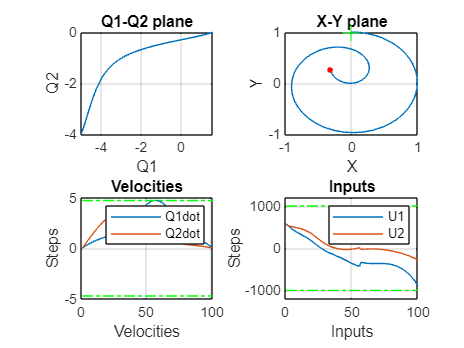

l1 = 0.5;
l2 = 0.5;
q1 = sol.value(X(1,:));
q2 = sol.value(X(2,:));
x = l1*cos(q1) + l2*cos(q1 + q2);
y = l1*sin(q1) + l2*sin(q1 + q2);

**PLOTS**

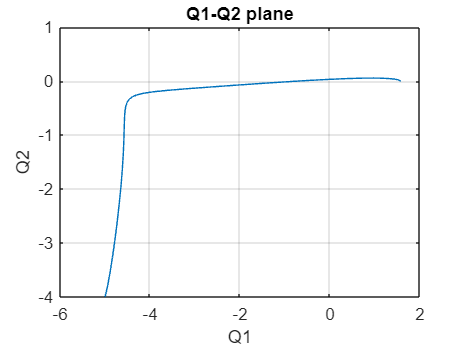

figure(1);
clf(1);
plot(q1', q2');
grid on;
hold on;
xlabel("Q1");
ylabel("Q2");
title('Q1-Q2 plane');

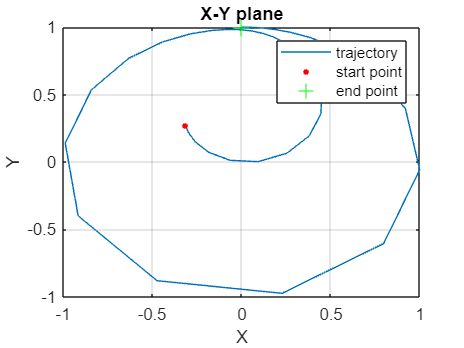


% Plot X-Y plane
figure(2);
clf(2);
plot(x', y');
grid on;
hold on;
xlabel("X");
ylabel("Y");
plot(x(1), y(1), 'r.', 'MarkerSize', 10);  % Start point
plot(x(end), y(end), 'g+', 'MarkerSize', 10);  % End point
legend('trajectory', 'start point', 'end point')
title('X-Y plane');

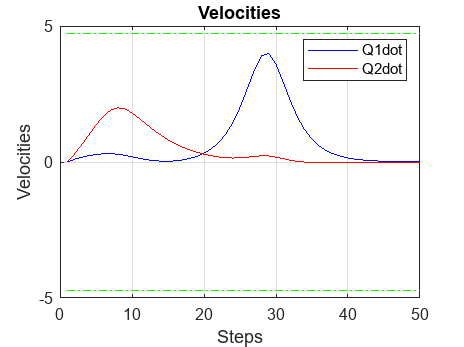


% Plot Velocities
figure(3);
clf(3);
plot(sol.value(X(3, :)'), 'b');
hold on;
plot(sol.value(X(4, :)'), 'r');
grid on;
plot(1:N+1, Qdotmin*ones(N+1,1), '-.g');
plot(1:N+1, Qdotmax*ones(N+1,1), '-.g');
xlabel("Steps");
ylabel("Velocities");
legend('Q1dot', 'Q2dot');
xlim([0 N]);
title('Velocities');

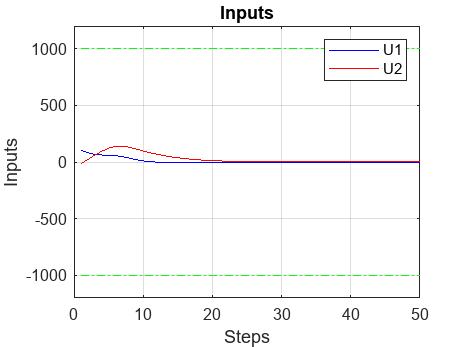


% Plot Inputs
figure(4);
clf(4);
plot(sol.value(U(1, :)'), 'b');
hold on;
plot(sol.value(U(2, :)'), 'r');
plot(1:N, Umin*ones(N,1), '-.g');
plot(1:N, Umax*ones(N,1), '-.g');
grid on;
xlabel("Steps");
ylabel("Inputs");
ylim([-1200 1200]);
xlim([0 N]);
legend('U1', 'U2');
title('Inputs');